# Tail wing mounting angle

CL_aw=5.3099 %radian^-1

CL_aw = 5.3099

CL_at=3.3624 %radian^-1

CL_at = 3.3624

cw=23.5511 % mean aerodynamic chord fo wing

cw = 23.5511

ct=17.3432 %ft ft horizontal tail wing mean aerodynamic chord length

ct = 17.3432

a_cruise=0.0175 %1deg AOA in radian

a_cruise = 0.0175

a_0w=-0.0524 %wing zero lift AOA -3deg

a_0w = -0.0524

a_0t=0 %tail wing zero lift AOA

a_0t = 0

xcg=17.5911

xcg = 17.5911

xw=xcg-0.25*cw %distance from wing ac to cg

xw = 11.7033

xt=-111.0855 %distance from tail wing ac to cg

xt = -111.0855

Sw=3779.3 %ft^2

Sw = 3.7793e+03

St=801.2417 %ft^2

St = 801.2417

Cm_aw=-0.0773 %zero lift moment coefficient of wing

Cm_aw = -0.0773

Cm_at=0 %zero lift moment coefficient of tail wing

Cm_at = 0

iw=0 %wing Mounting Angle

iw = 0

Cm_cruise=0

Cm_cruise = 0


it=((Cm_cruise-Cm_aw-(Cm_at*ct/cw*St/Sw)-(CL_aw/cw*(a_cruise-a_0w-a_0t)*(xw)))/(CL_at/cw*(St/Sw)*xt))-a_cruise+a_0t

it = 0.0144

%tail wing Mounting Angle
it_deg=it*180/pi

it_deg = 0.8231

v=667.6       %ft/s          

v = 667.6000

d=7.38*10^-4  %slug/ft^3 @35000ft

d = 7.3800e-04

CL_wcruise=0.3707

CL_wcruise = 0.3707


CL_alpha=3.3624

CL_alpha = 3.3624

zeroL_AOA=0

zeroL_AOA = 0

aoa=-5:0.25:10;
CL_curve=(CL_alpha*pi/180)*(aoa-zeroL_AOA)

CL_curve =    -0.2934   -0.2788   -0.2641   -0.2494   -0.2347   -0.2201   -0.2054   -0.1907   -0.1761   -0.1614   -0.1467   -0.1320   -0.1174   -0.1027   -0.0880   -0.0734   -0.0587   -0.0440   -0.0293   -0.0147         0    0.0147    0.0293    0.0440    0.0587    0.0734    0.0880    0.1027    0.1174    0.1320    0.1467    0.1614    0.1761    0.1907    0.2054    0.2201    0.2347    0.2494    0.2641    0.2788    0.2934    0.3081    0.3228    0.3374    0.3521    0.3668    0.3815    0.3961    0.4108    0.4255


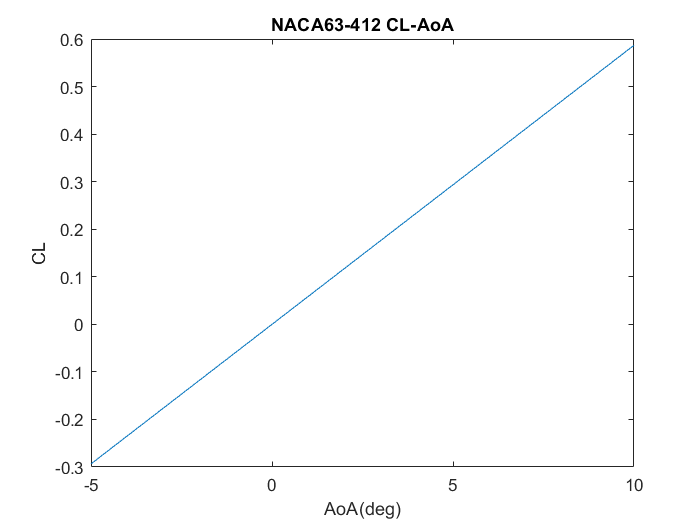

plot(aoa,CL_curve)
title('NACA63-412 CL-AoA')
xlabel('AoA(deg)')
ylabel('CL')


CL_tcruise=0.058685

CL_tcruise = 0.0587


L_w=0.5*d*v^2*Sw*CL_wcruise

L_w = 2.3041e+05

L_t=0.5*d*v^2*St*CL_tcruise

L_t = 7.7330e+03

L=L_t+L_w

L = 2.3814e+05

##  moment about cg with respect to AOA

AOA=-5:0.1:10 

AOA =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


a_0w1=-3 %wing zero lift AOA deg

a_0w1 = -3

it1=it*180/pi

it1 = 0.8231


Cm_cg=CL_aw*pi/180*(AOA-a_0w1+iw)*xw/cw+CL_at*pi/180*(AOA-a_0t+it1)*xt*(St/Sw)/cw+Cm_aw+Cm_at*(St/Sw)*(ct/cw)

Cm_cg =     0.0757    0.0745    0.0732    0.0719    0.0707    0.0694    0.0681    0.0669    0.0656    0.0643    0.0631    0.0618    0.0606    0.0593    0.0580    0.0568    0.0555    0.0542    0.0530    0.0517    0.0505    0.0492    0.0479    0.0467    0.0454    0.0441    0.0429    0.0416    0.0403    0.0391    0.0378    0.0366    0.0353    0.0340    0.0328    0.0315    0.0302    0.0290    0.0277    0.0265    0.0252    0.0239    0.0227    0.0214    0.0201    0.0189    0.0176    0.0163    0.0151    0.0138


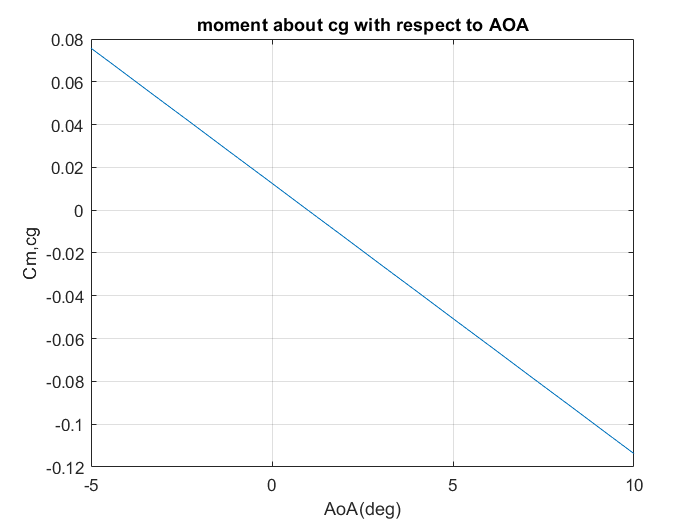

plot(AOA,Cm_cg)
title('moment about cg with respect to AOA')
xlabel('AoA(deg)')
ylabel('Cm,cg')
grid on